**Task1: Calculating snow depth from reported range and confirming the anomaly in sensor readings**

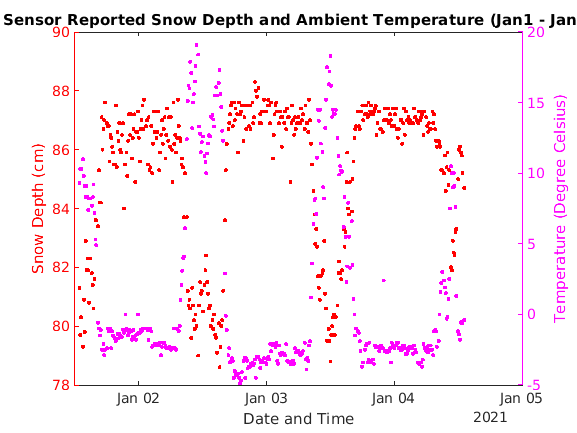

%Imported data from the excel file and changed the datetime format to
%MM/dd/yyyy HH:mm

%Extracting data

range = snowDataJan1_4.Reported_range_in_cm;
date_time = snowDataJan1_4.Date_and_Time;
temp = snowDataJan1_4.Temperature_in_degree_celcius;
rain_data = snowDataJan1_4.Daily_accumulative_rain_in_mm;

%Calculating Range

height = 310; %Known
snow_depth = height - range;

yyaxis left %For 2 axis on the same fig

%Setting y-axis color

set(gca, 'YTickLabel', [])
set(gca, 'YTick', [])
set(gca, 'ycolor', 'r') 

%Plotting Data

plot(date_time, snow_depth, "r.")
title("Sensor Reported Snow Depth and Ambient Temperature (Jan1 - Jan4)")
xlabel("Date and Time")
ylabel("Snow Depth (cm)")

yyaxis right

set(gca, 'YTickLabel', [])
set(gca, 'YTick', [])
set(gca, 'ycolor', 'm') 

plot(date_time, temp, "m.")
ylabel("Temperature (Degree Celsius)")

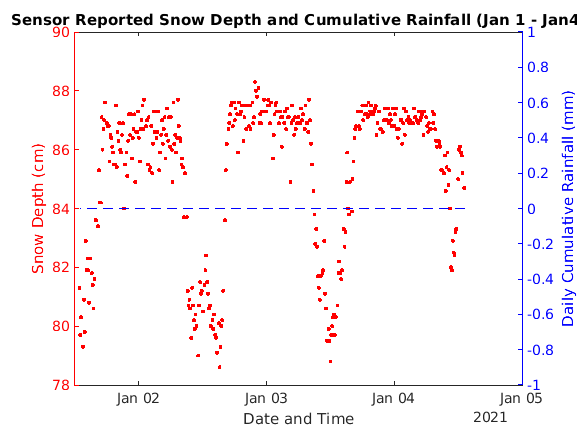


figure;

yyaxis left

set(gca, 'YTickLabel', [])
set(gca, 'YTick', [])
set(gca, 'ycolor', 'r') 

plot(date_time, snow_depth, "r.")
title("Sensor Reported Snow Depth and Cumulative Rainfall (Jan 1 - Jan4)")
xlabel("Date and Time")
ylabel("Snow Depth (cm)")

yyaxis right

set(gca, 'YTickLabel', [])
set(gca, 'YTick', [])
set(gca, 'ycolor', 'b')

plot(date_time, rain_data, "b--")
ylabel("Daily Cumulative Rainfall (mm)")

**Task2: Determining the variation in ranger error against variation in temperature**

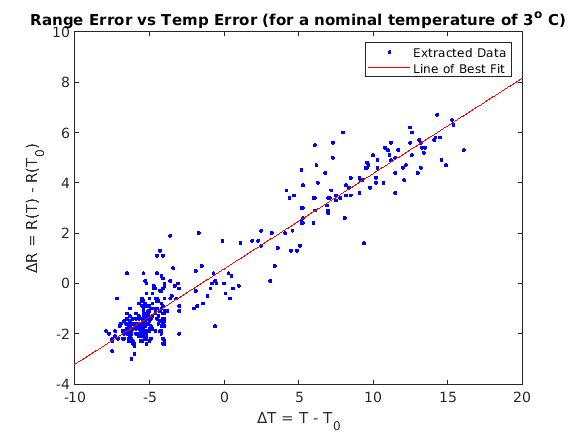

% Task 2 %
% Using the formula ΔR = c x ΔT, c is the gradient of the function. To find
% the gradient we will use the intrinsic function already present in MATLAB
% known as the linear fit.

%Extracting Data

temp = snowDataJan1_4.Temperature_in_degree_celcius;
range = snowDataJan1_4.Reported_range_in_cm;
T_0 = 3;         % baseline temperature at index 24. 3 degrees is present on only at one index in the data 
                 % thus it is uniqueand can be considered as baseline.
R_0 = range(24); % Value of range present at the index of the basline.

% for ΔT and ΔR

delta_T = temp - T_0;
delta_R = range - R_0;

%Plotting Data

figure;

plot(delta_T, delta_R, "b.")
title("Range Error vs Temp Error (for a nominal temperature of 3^o C)")
xlabel("ΔT = T - T_0")
ylabel("ΔR = R(T) - R(T_0)")

hold on;

%Line of Best Fit (Equation found using Basic Fitting in MATLAB)

x = -10 : 0.05 : 20;
y = (0.3791 * x) + 0.5734;
plot(x, y, "r")
legend(["Extracted Data" "Line of Best Fit"])

hold off;

**Task3: Applying the compensation**

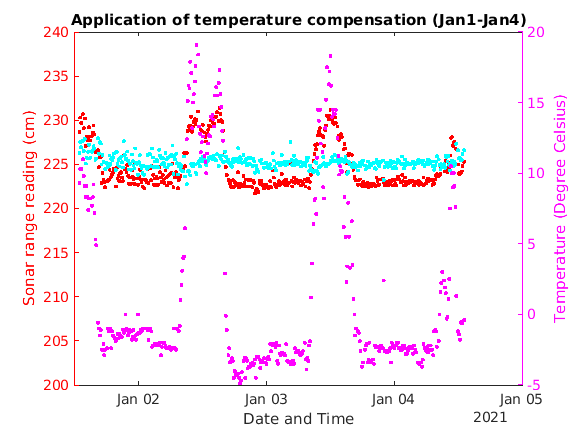

%Extracting Data and defining constants

temp = snowDataJan1_4.Temperature_in_degree_celcius;
range = snowDataJan1_4.Reported_range_in_cm;
date_time = snowDataJan1_4.Date_and_Time;

c = 0.3791;                    %Found in Task 2
T_0 = 3;                       %Declared in Task 1

R_T = zeros(1, length(range)); %Initialising Compensated Range Array

for i = 1: length(range)
    delta_T = T_0 - temp(i) ;
    delta_R = c * delta_T;
    R_T(i) = delta_R + range(i);
end

figure;

yyaxis left %For 2 axis on the same fig

%Setting y-axis color

set(gca, 'YTickLabel', [])
set(gca, 'YTick', [])
set(gca, 'ycolor', 'r') 

%Plotting Data

plot(date_time, range, "r.")
title("Application of temperature compensation (Jan1-Jan4)")
xlabel("Date and Time")
ylabel("Sonar range reading (cm)")

hold on;

plot(date_time, R_T, "c.")

ylim([200 240])

hold off;

yyaxis right

set(gca, 'YTickLabel', [])
set(gca, 'YTick', [])
set(gca, 'ycolor', 'm') 

plot(date_time, temp, "m.")
ylabel("Temperature (Degree Celsius)")

**Task4: Compensating the entire data**

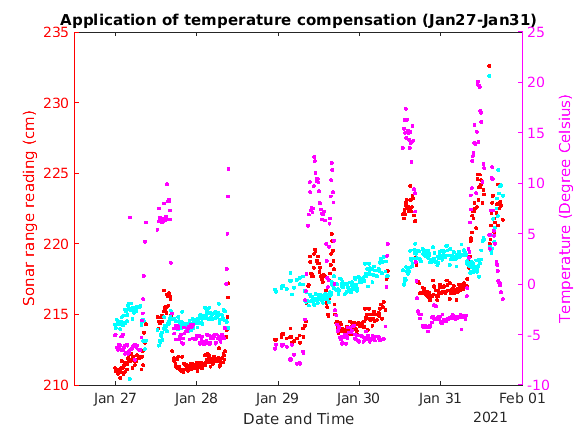

%Extracting Data and defining constants

temp_task4 = snowDataCompleteSet.Temperature_in_degree_celcius;
range_T0 = snowDataCompleteSet.Reported_range_in_cm;
date_time = snowDataCompleteSet.Date_and_Time;

c = 0.3791;                    %Found in Task 2
T_0 = 3;                       %Declared in Task 1

range_T = zeros(1, length(range_T0));

for i = 1 : length(range_T0)
    delta_T = T_0 - temp_task4(i) ;
    delta_R = c * delta_T;
    range_T(i) = delta_R + range_T0(i);
end


figure;

yyaxis left %For 2 axis on the same fig

%Setting y-axis color

set(gca, 'YTickLabel', [])
set(gca, 'YTick', [])
set(gca, 'ycolor', 'r') 

%Plotting Data
%Jan27-31
plot(date_time(838:1263), range_T0(838:1263), "r.")
title("Application of temperature compensation (Jan27-Jan31)")
xlabel("Date and Time")
ylabel("Sonar range reading (cm)")

hold on;

plot(date_time(838:1263), range_T(838:1263), "c.")

hold off;

yyaxis right

set(gca,'YTickLabel',[])
set(gca,'YTick',[])
set(gca,'ycolor','m') 

plot(date_time(838:1263), temp_task4(838:1263), "m.")
ylabel("Temperature (Degree Celsius)")

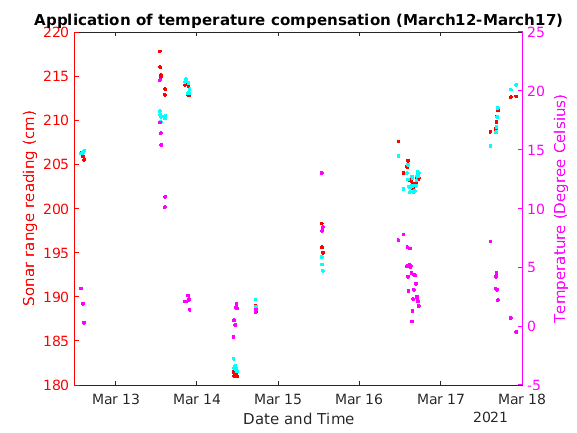


%Mar12-17
figure;

yyaxis left %For 2 axis on the same fig

%Setting y-axis color

set(gca, 'YTickLabel', [])
set(gca, 'YTick', [])
set(gca, 'ycolor', 'r') 

%Plotting Data

plot(date_time(624:680), range_T0(624:680), "r.")
title("Application of temperature compensation (March12-March17)")
xlabel("Date and Time")
ylabel("Sonar range reading (cm)")

hold on;

plot(date_time(624:680), range_T(624:680), "c.")

hold off;

yyaxis right

set(gca, 'YTickLabel', [])
set(gca, 'YTick', [])
set(gca, 'ycolor', 'm') 

plot(date_time(624:680), temp_task4(624:680), "m.")
ylabel("Temperature (Degree Celsius)")

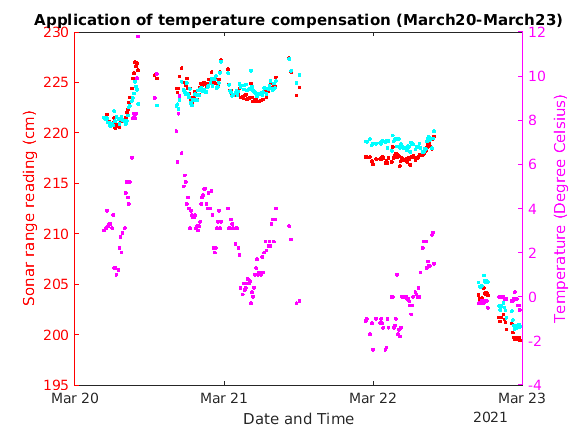


%Mar20-23
figure;

yyaxis left %For 2 axis on the same fig

%Setting y-axis color

set(gca, 'YTickLabel', [])
set(gca, 'YTick', [])
set(gca, 'ycolor', 'r') 

%Plotting Data

plot(date_time(407:602), range_T0(407:602), "r.")
title("Application of temperature compensation (March20-March23)")
xlabel("Date and Time")
ylabel("Sonar range reading (cm)")

hold on;

plot(date_time(407:602), range_T(407:602), "c.")

hold off;

yyaxis right

set(gca,'YTickLabel',[])
set(gca,'YTick',[])
set(gca,'ycolor','m') 

plot(date_time(407:602), temp_task4(407:602), "m.")
ylabel("Temperature (Degree Celsius)")